# パラメータを更新

run('parameters.m');

# 台形加速をプロット

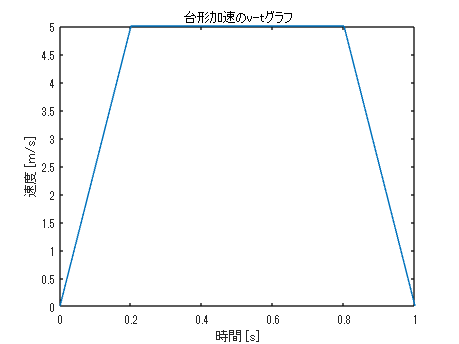

delta_t = 0.001; % シミュレーションのステップ時間
simulation_time = 1; % シミュレーションの時間[s]

t = 0 : delta_t : simulation_time; % 時間
velocity = zeros(1, length(t));
v0 = 0;
velocity(1) = v0; % 初速 [m/s]

acc_time = (max_velocity - v0) / max_acceleration; % 加速&減速にかかる時間[s]
const_time = simulation_time - 2 * acc_time; %等速で動く時間[s]

% シミュレーション
time = 0;
for i = 2 : length(t)
    if 0 <= time && time <= acc_time % 加速時間
        velocity(i) = velocity(i-1) + max_acceleration * delta_t;
        if(velocity(i) >= max_velocity) 
            velocity(i) = max_velocity;
        end
    elseif acc_time < time && time <= (acc_time + const_time) % 等速時間
        velocity(i) = max_velocity;
    elseif (acc_time + const_time) < time && time <= simulation_time % 減速時間
        velocity(i) = velocity(i-1) - max_acceleration * delta_t;
    end
    
    time = time + delta_t;
end

velocity(end) = v0;

% プロット
t = 0 : delta_t : simulation_time;
plot(t, velocity);
xlabel('時間 [s]')
ylabel('速度 [m/s]')
% ylim([0 5.3])
title('台形加速のv-tグラフ')

# モータの特性をプロット

#### 回転数-トルク特性

% sloop = -n_max / T_max; %傾きを計算
% fplot(@(x) sloop * x + n_max, [0 T_max]);
torque_motor = linspace(0, T_max);
n_motor = linspace(n_max, 0);
plot(torque_motor, n_motor);
xlabel("トルク [Nm]")
ylabel("回転数 [rpm]")

#### 出力特性

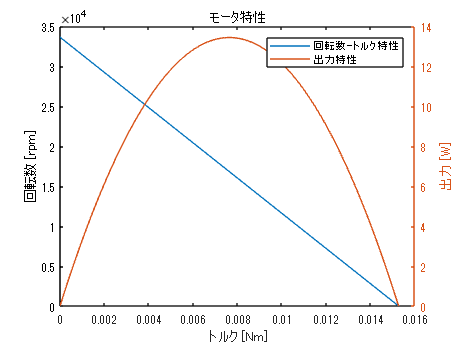

omega_motor = linspace(omega_max, 0);
P_motor = torque_motor .* omega_motor; %出力を計算

hold on
yyaxis right
plot(torque_motor, P_motor);
ylabel("出力 [W]")
legend("回転数-トルク特性", "出力特性")
title("モータ特性")

cla reset
hold off

P_motor = max(double(P_motor)) %モータの最大出力

P_motor = 13.4220

p_motor = (omega_max / 2) * (T_max / 2) % 厳密解

p_motor = 13.4234

# タイヤに必要な出力を算出

対向2輪ロボットで，各車輪は1つのモータで駆動していると仮定します．

% タイヤに必要な角速度とトルク．走行抵抗などで余計にトルクが必要な場合を効率として考慮
omega_tire_need = (max_velocity / r);
torque_tire_need = (r * (m/2) * max_acceleration) / eta; % タイヤが2個ついているので1つのタイヤにかかる重量は半分

% タイヤに必要な出力（効率考慮済み）
P_tire_need = omega_tire_need * torque_tire_need

P_tire_need = 10.7143

# 減速比を考慮して駆動点を満たせるか確認

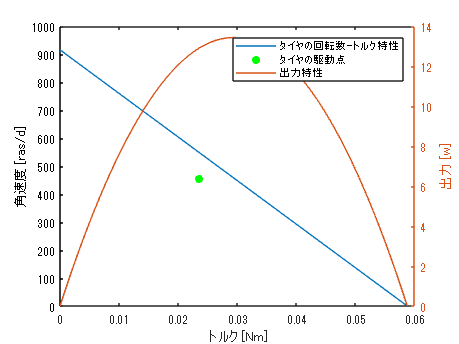

%減速比をかけた角速度-トルク曲線をプロット
ratio = 0.26;
torque_motor_ratio = torque_motor / ratio;
omega_motor_ratio = omega_motor * ratio;

plot(torque_motor_ratio, omega_motor_ratio); % 角速度-トルク特性
xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")

% 出力をプロット
P_ratio_num = torque_motor_ratio .* omega_motor_ratio; %出力を計算
yyaxis right
hold on
plot(torque_motor_ratio, P_ratio_num); % 出力特性
ylabel("出力 [w]")

% 加減速時の駆動点をプロット
yyaxis left
scatter(torque_tire_need, omega_tire_need, "green", 'filled'); %駆動点
hold off

legend("タイヤの回転数-トルク特性", "タイヤの駆動点", "出力特性")